# EKF Equations

N = 4;
tau = 25;
lambda = 0.25;
syms dt
syms a [3 1]
syms q [4 1]
syms w [3 1]
syms theta [N 1]
syms theta_dot [N 1]
syms u [N 1]

x_k = [a; q; w; theta; theta_dot];

s = sqrt((w(1)*dt)^2 + (w(2)*dt)^2 + (w(3)*dt)^2)/2;
Psi = [0 w(1) w(2) w(3);
       -w(1) 0 -w(3) w(2);
       -w(2) w(3) 0 -w(1);
       -w(3) -w(2) w(1) 0];

q_k1 = (eye(4)*cos(s) - (Psi*dt/2)*(sin(s)/s))*q;
x_k1 = [exp(-tau*dt)*a;
        q_k1;
        w;
        theta + theta_dot*dt;
        (1-lambda)*theta_dot + lambda*u]

$$x\_k1 = \begin{array}{l} \left(\begin{array}{c} a_{1}\,{\mathrm{e}}^{-25\,\mathrm{dt}}\\ a_{2}\,{\mathrm{e}}^{-25\,\mathrm{dt}}\\ a_{3}\,{\mathrm{e}}^{-25\,\mathrm{dt}}\\ q_{1}\,\cos\left(\frac{\sigma_{1}}{2}\right)-\frac{\mathrm{dt}\,q_{2}\,w_{1}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}-\frac{\mathrm{dt}\,q_{3}\,w_{2}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}-\frac{\mathrm{dt}\,q_{4}\,w_{3}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}\\ q_{2}\,\cos\left(\frac{\sigma_{1}}{2}\right)+\frac{\mathrm{dt}\,q_{1}\,w_{1}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}+\frac{\mathrm{dt}\,q_{3}\,w_{3}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}-\frac{\mathrm{dt}\,q_{4}\,w_{2}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}\\ q_{3}\,\cos\left(\frac{\sigma_{1}}{2}\right)+\frac{\mathrm{dt}\,q_{1}\,w_{2}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}-\frac{\mathrm{dt}\,q_{2}\,w_{3}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}+\frac{\mathrm{dt}\,q_{4}\,w_{1}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}\\ q_{4}\,\cos\left(\frac{\sigma_{1}}{2}\right)+\frac{\mathrm{dt}\,q_{1}\,w_{3}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}+\frac{\mathrm{dt}\,q_{2}\,w_{2}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}-\frac{\mathrm{dt}\,q_{3}\,w_{1}\,\sin\left(\frac{\sigma_{1}}{2}\right)}{\sigma_{1}}\\ w_{1}\\ w_{2}\\ w_{3}\\ \theta_{1}+\mathrm{dt}\,\theta_{\mathrm{dot1}}\\ \theta_{2}+\mathrm{dt}\,\theta_{\mathrm{dot2}}\\ \theta_{3}+\mathrm{dt}\,\theta_{\mathrm{dot3}}\\ \theta_{4}+\mathrm{dt}\,\theta_{\mathrm{dot4}}\\ \frac{3\,\theta_{\mathrm{dot1}}}{4}+\frac{u_{1}}{4}\\ \frac{3\,\theta_{\mathrm{dot2}}}{4}+\frac{u_{2}}{4}\\ \frac{3\,\theta_{\mathrm{dot3}}}{4}+\frac{u_{3}}{4}\\ \frac{3\,\theta_{\mathrm{dot4}}}{4}+\frac{u_{4}}{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\mathrm{dt}}^{2}\,{w_{1}}^{2}+{\mathrm{dt}}^{2}\,{w_{2}}^{2}+{\mathrm{dt}}^{2}\,{w_{3}}^{2}} \end{array}$$


F = jacobian(x_k1, x_k)

% save as matlab functions
matlabFunction(x_k1, "File", "process_model", "Vars", {x_k, u, dt})

ans = function_handle with value:
    @process_model


matlabFunction(F, "File", "process_jacobian", "Vars", {x_k, u, dt})

ans = function_handle with value:
    @process_jacobian


## Test Prediction Step

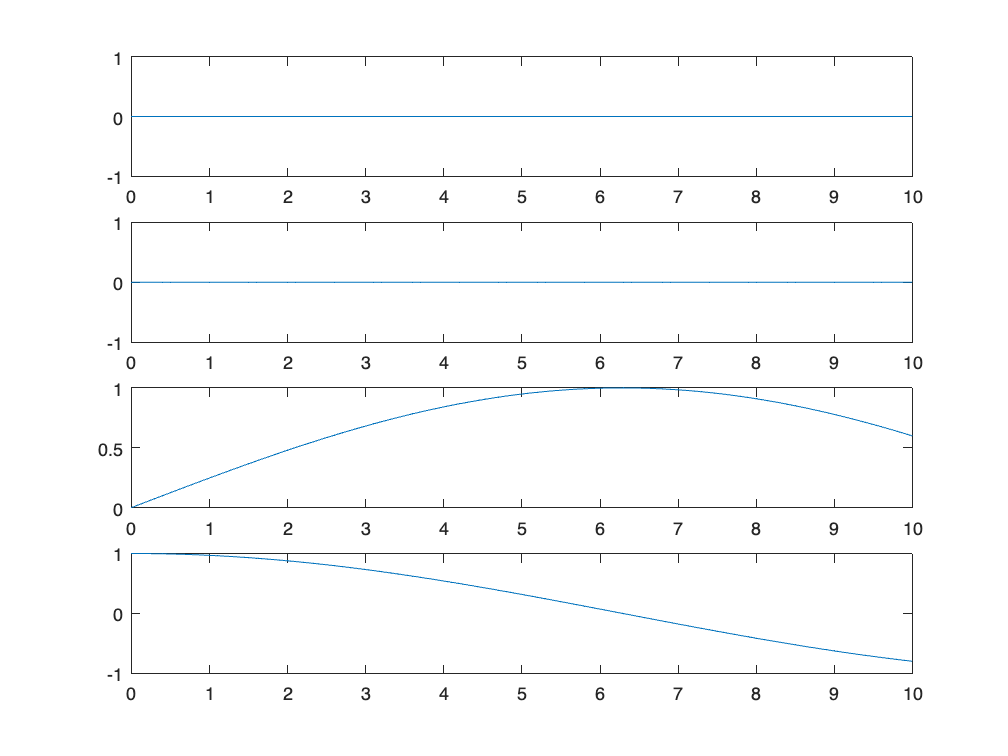

N_x = 10+2*N;
a0 = zeros(3,1);
q0 = [0; 0; 0; 1];
w0 = [0.5; 0; 0];
theta0 = zeros(N,1);
theta_dot0 = zeros(N,1);
x0 = [a0; q0; w0; theta0; theta_dot0];

P0 = eye(N_x)*1e-4;
Q = eye(N_x)*1e-2;

dt = 0.1;
times = 0:dt:10;
x = zeros(N_x, length(times));
P = zeros(N_x, N_x, length(times));
x(:,1) = x0;
P(:,:,1) = P0;
u = zeros(N,1);
for k = 1:length(times)-1
    x(:,k+1) = process_model(x(:,k), u, dt);
    F = process_jacobian(x(:,k), u, dt);
    P(:,:,k+1) = F*P(:,:,k)*F.' + Q;
end

q = x(4:7,:);
figure
subplot(4,1,1)
plot(times, q(1,:))

subplot(4,1,2)
plot(times, q(2,:))

subplot(4,1,3)
plot(times, q(3,:))

subplot(4,1,4)
plot(times, q(4,:))

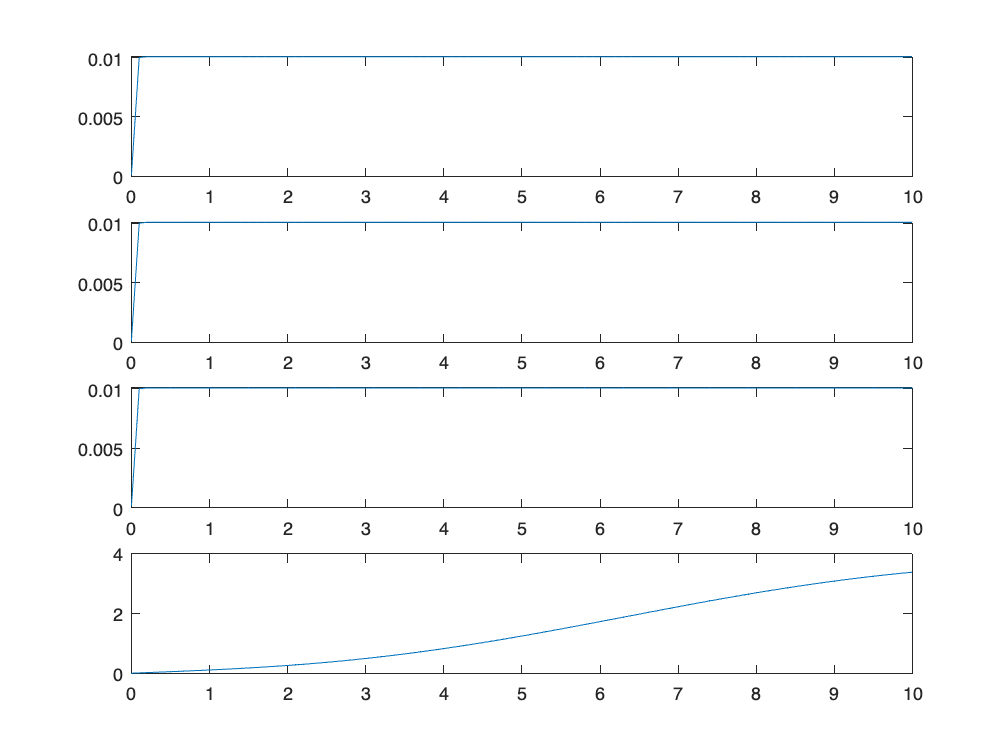


P_q = P(4:7, 4:7, :);
figure
subplot(4,1,1)
plot(times, squeeze(P(1,1,:)))

subplot(4,1,2)
plot(times, squeeze(P(2,2,:)))

subplot(4,1,3)
plot(times, squeeze(P(3,3,:)))

subplot(4,1,4)
plot(times, squeeze(P(4,4,:)))

## Forward Kinematics

syms l i
w1 = [1; 0; 0];
w2 = [0; 0; 1];
q = [0; l*(i-1/2); 0];
cross(-w1, q)
cross(-w2, q)
